002_2，使用训练好的网络执行语义分割并且保存预测图像

Running semantic segmentation network
-------------------------------------
* Processed 13 images.



Evaluating semantic segmentation results
----------------------------------------
* Selected metrics: global accuracy, class accuracy, IoU, weighted IoU, BF score.
* Processed 13 images.
* Finalizing... Done.
* Data set metrics:

     GlobalAccuracy        MeanAccuracy            MeanIoU            WeightedIoU          MeanBFScore   
    _________________    _________________    _________________    _________________    _________________

    0.844627967247596    0.842788980247972    0.636516830078065    0.765522350522457    0.844245156097725



ans = 2×2 table
                    Sand      Medium_Rock
                   _______    ___________

    Sand           2443141      446675   
    Medium_Rock      82813      435243   


name = "003_confusionchart_2024-03-01-17-16.png"

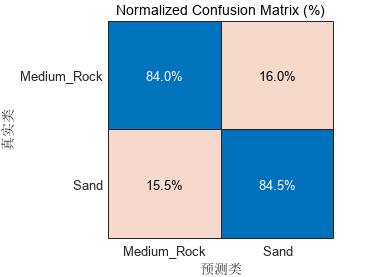

do_prediction=1;
if do_prediction
    %加载数据集
    clc
    clear
    load imageLabelData002_2\gTruth_sand_mediumrock_001_train.mat
    [imdstrain,pxdstrain]=pixelLabelTrainingData(gTruth);
    load imageLabelData002_2\gTruth_sand_mediumrock_001_test3.mat
    [imdstest,pxdstest]=pixelLabelTrainingData(gTruth);
    %加载训练好的网络
    load Result002_2\001_DeepLabv3+_resnet50_2023-12-01-17-37.mat
    %执行预测
    pxdsresult=semanticseg(imdstest,net,"MiniBatchSize",10);
    metrics=evaluateSemanticSegmentation(pxdsresult,pxdstest);
    metrics.ConfusionMatrix
    classname=pxdstrain.ClassNames;
    pixelLabelID = gTruth.LabelDefinitions.PixelLabelID ;
    figure
    cm = confusionchart(metrics.ConfusionMatrix.Variables, ...
      classname, Normalization='row-normalized');
    cm.Title = 'Normalized Confusion Matrix (%)';
    modelDateTime = string(datetime("now",Format="yyyy-MM-dd-HH-mm"));
    name=strcat('003_confusionchart_',string(modelDateTime),'.png')
    saveas(gcf,strcat('Result002_2\',name))
end

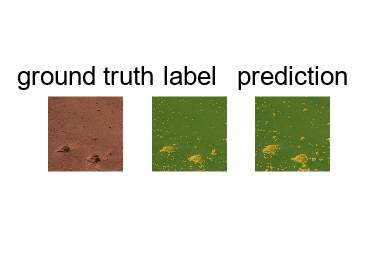

%保存预测结果
do_show_002_2=1;
if do_show_002_2
    im_prediction_location=dir("*.png");
    im_prediction_location=natsortfiles(im_prediction_location);
    %cmap=gTruth.LabelDefinitions.LabelColor;
    cmap=[0 0.6 0;1 1 0.07];
    imwritelocation='Result002_2\image\';
    imFrom='testSet_';
    for i=1:numel(im_prediction_location)
        I1=imread(imdstest.Files{i});
        subplot(1,3,1);
        imshow(I1);
        title('ground truth','FontSize',20);
        
        C1=imread(pxdstest.Files{i});
        subplot(1,3,2);
        I2 = labeloverlay(I1,C1,"Colormap",cmap, ...
                    "Transparency",0.6);
        imshow(I2);
        title('label','FontSize',20);
    
        C2=imread(im_prediction_location(i).name);
        subplot(1,3,3);
        I3 = labeloverlay(I1,C2,"Colormap",cmap, ...
                    "Transparency",0.6);
        imshow(I3);
        title('prediction','FontSize',20);
        saveas(gcf,strcat(imwritelocation,imFrom,string(i),'_','show','.png'))
        
        I1_name=strcat(imwritelocation,imFrom,string(i),'_','1_G','.png');
        imwrite(I1,I1_name)
        I2_name=strcat(imwritelocation,imFrom,string(i),'_','2_L','.png');
        imwrite(I2,I2_name)
        I3_name=strcat(imwritelocation,imFrom,string(i),'_','3_P','.png');
        imwrite(I3,I3_name)
    end
    delete('*.png')
end